# 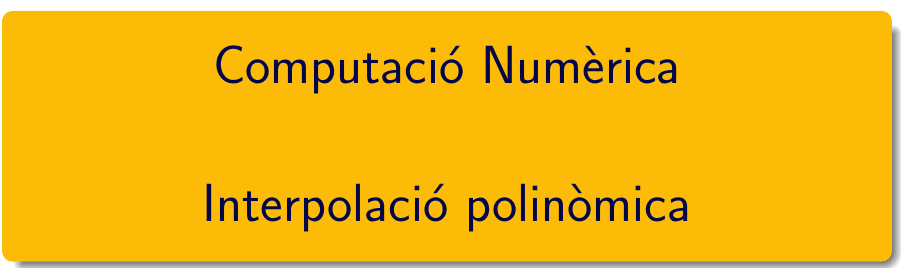

================================================================================

# Pràctica 6 - Interpolació polinònimca i ajust de dades (II)

`document preparat per M. Àngela Grau Gotés - març 2023`

## PRACTIQUEM ....

clearvars; clf

### 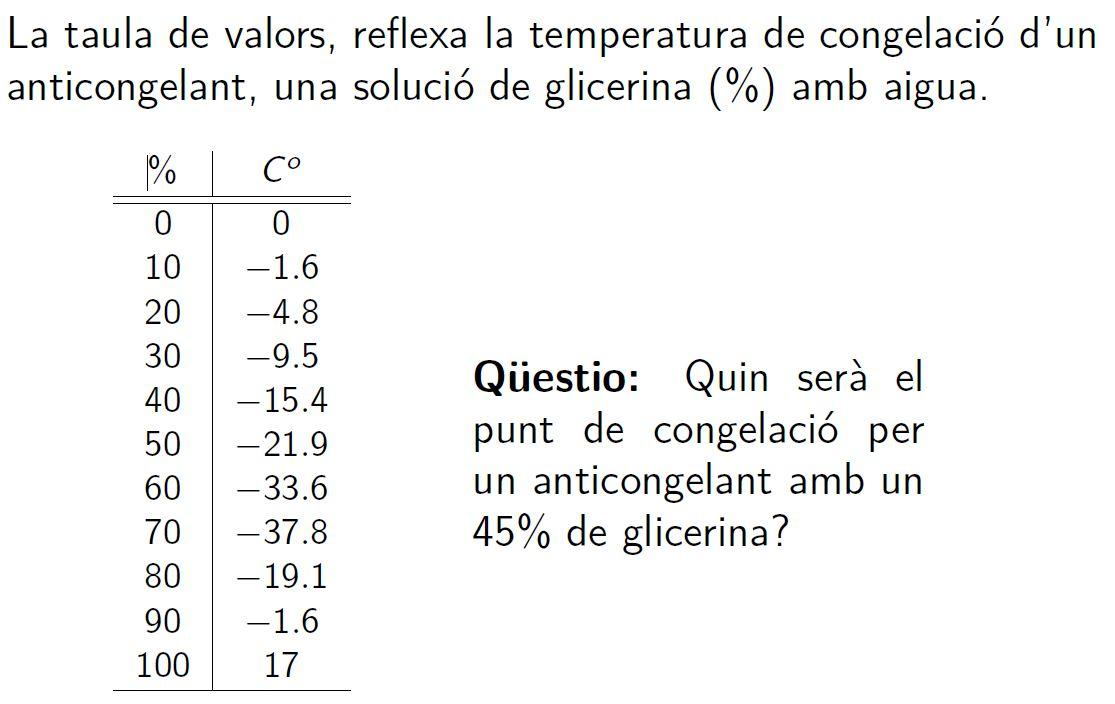

### Dar una estimación del punto de congelación per **45%** de glicerol.

Aquest exercici s'ha de resoldre fent ús de **polyinterp**

- Gráfica de los datos

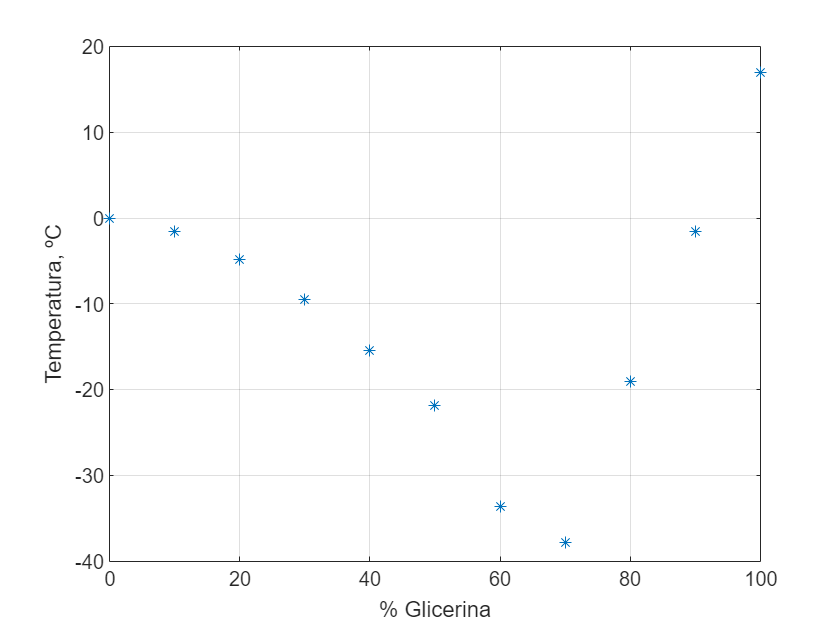

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
plot(x,y,'*')

grid on
ylabel('Temperatura, ºC')
xlabel('% Glicerina')

#### Exercici 1. Recta de interpolación

- Caso 1. Polinomio de grado 1

% Datos
porcentaje = [0 10 20 30 40 50 60 70 80 90 100];
temperatura = [0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];

% Interpolación con polinomio de grado 1 (recta)
p1 = polyinterp(porcentaje, temperatura, 1);

% Evaluar el polinomio en 45% de glicerol
x_pred = 45;
y_pred = polyval(p1, x_pred)

y_pred =        3.6684


- Grafica de los datos y el polinomio obtenido

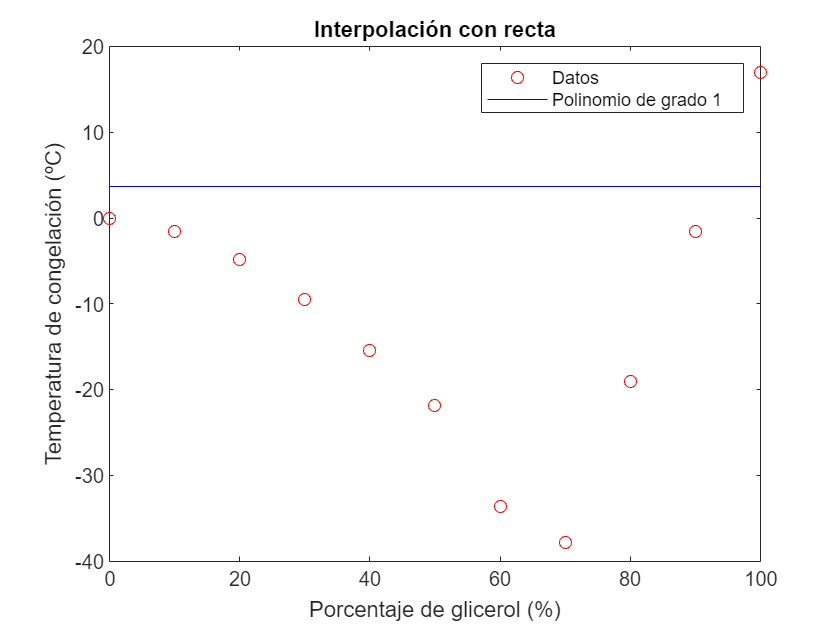

% Graficar los datos y el polinomio obtenido
x_plot = linspace(0, 100, 100);
y_plot = polyval(p1, x_plot);

figure
plot(porcentaje, temperatura, 'ro', x_plot, y_plot, 'b-');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Polinomio de grado 1');
title('Interpolación con recta');

#### Exercici 2. Polinomi interpolador de grau 3

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

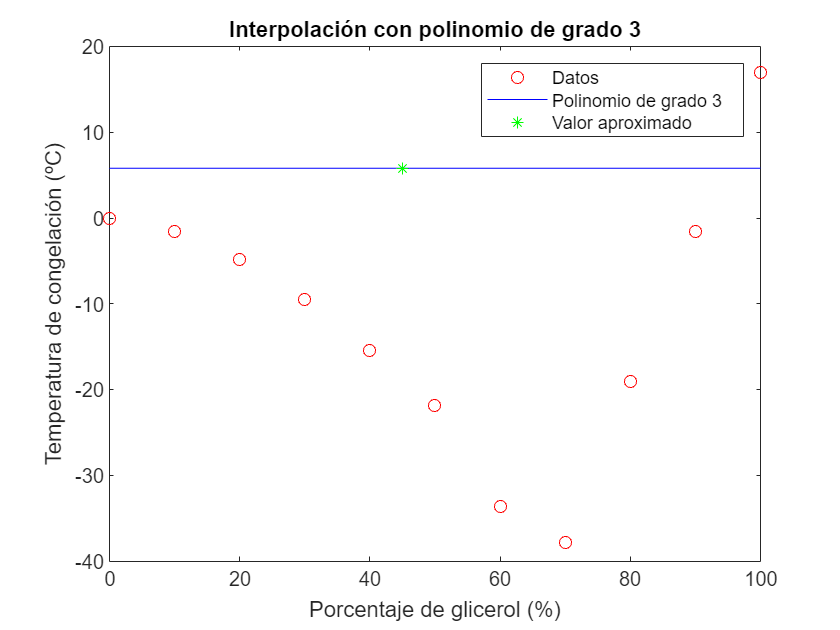

% Interpolación con polinomio de grado 3
p3 = polyinterp(porcentaje, temperatura, 3);

% Evaluar el polinomio en 45% de glicerol
y_pred_grado3 = polyval(p3, x_pred);

% Graficar los datos, el valor aproximado y el polinomio interpolador
y_plot_grado3 = polyval(p3, x_plot);

figure
plot(porcentaje, temperatura, 'ro', x_plot, y_plot_grado3, 'b-', x_pred, y_pred_grado3, 'g*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Polinomio de grado 3', 'Valor aproximado');
title('Interpolación con polinomio de grado 3');

#### Exercici 3. Polinomi interpolador de grau 10

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

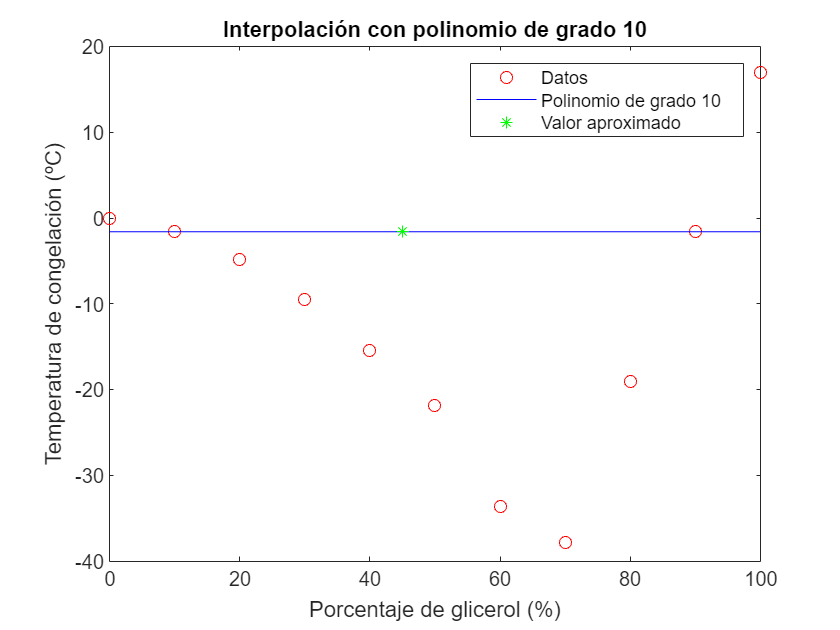

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
% Interpolación con polinomio de grado 10
p10 = polyinterp(porcentaje, temperatura, 10);

% Evaluar el polinomio en 45% de glicerol
y_pred_grado10 = polyval(p10, x_pred);

% Graficar los datos, el valor aproximado y el polinomio interpolador
y_plot_grado10 = polyval(p10, x_plot);

figure
plot(porcentaje, temperatura, 'ro', x_plot, y_plot_grado10, 'b-', x_pred, y_pred_grado10, 'g*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Polinomio de grado 10', 'Valor aproximado');
title('Interpolación con polinomio de grado 10');

#### Exercici 4. Spline lineal  (interpolació lineal a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

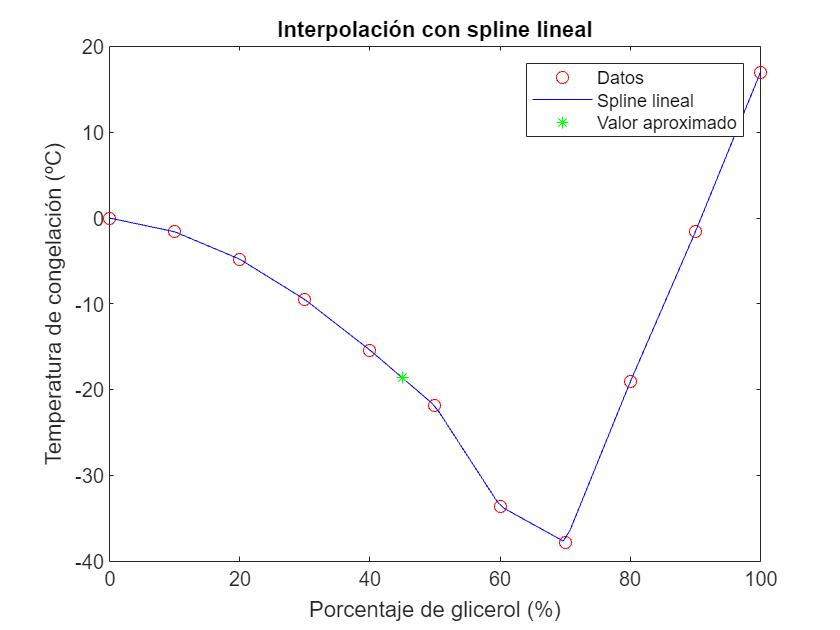

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
% Spline lineal (interpolación lineal a trozos)
spline_lineal = interp1(porcentaje, temperatura, x_plot, 'linear');

% Evaluar el spline lineal en 45% de glicerol
y_pred_spline_lineal = interp1(porcentaje, temperatura, x_pred, 'linear');

% Graficar los datos, el valor aproximado y el spline lineal
figure
plot(porcentaje, temperatura, 'ro', x_plot, spline_lineal, 'b-', x_pred, y_pred_spline_lineal, 'g*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Spline lineal', 'Valor aproximado');
title('Interpolación con spline lineal');

#### Exercici 5. Spline cúbic  (interpolació cúbica a trossos)

- Valor aproximat polinomi

- Grafica de les dades, el valor aproximat i el polinomi interpolador

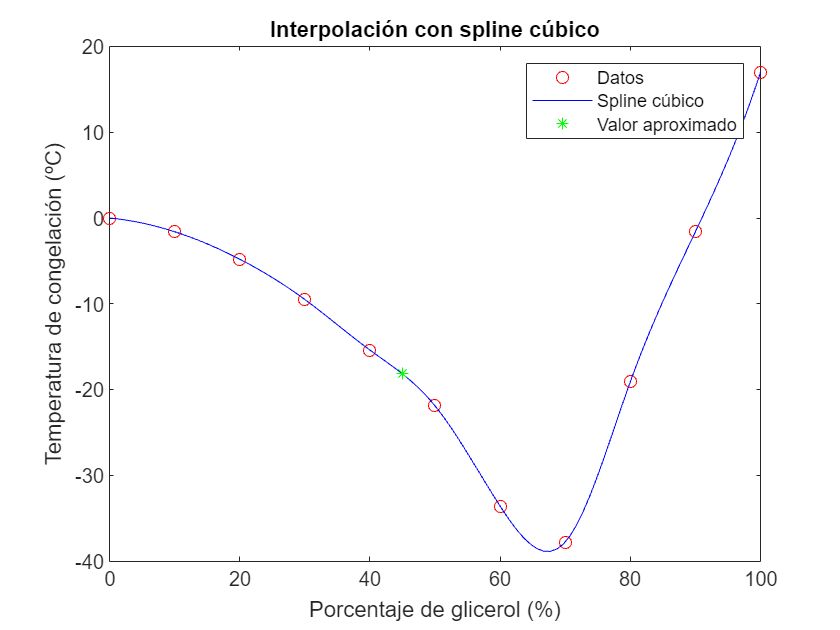

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
% Spline cúbico (interpolación cúbica a trozos)
spline_cubico = interp1(porcentaje, temperatura, x_plot, 'spline');

% Evaluar el spline cúbico en 45% de glicerol
y_pred_spline_cubico = interp1(porcentaje, temperatura, x_pred, 'spline');

% Graficar los datos, el valor aproximado y el spline cúbico
figure
plot(porcentaje, temperatura, 'ro', x_plot, spline_cubico, 'b-', x_pred, y_pred_spline_cubico, 'g*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Spline cúbico', 'Valor aproximado');
title('Interpolación con spline cúbico');

#### Exercici 6. Ajust per mínims quadrats (recta)

- Valor aproximat recta

- Grafica de les dades, el valor aproximat i el polinomi interpolador

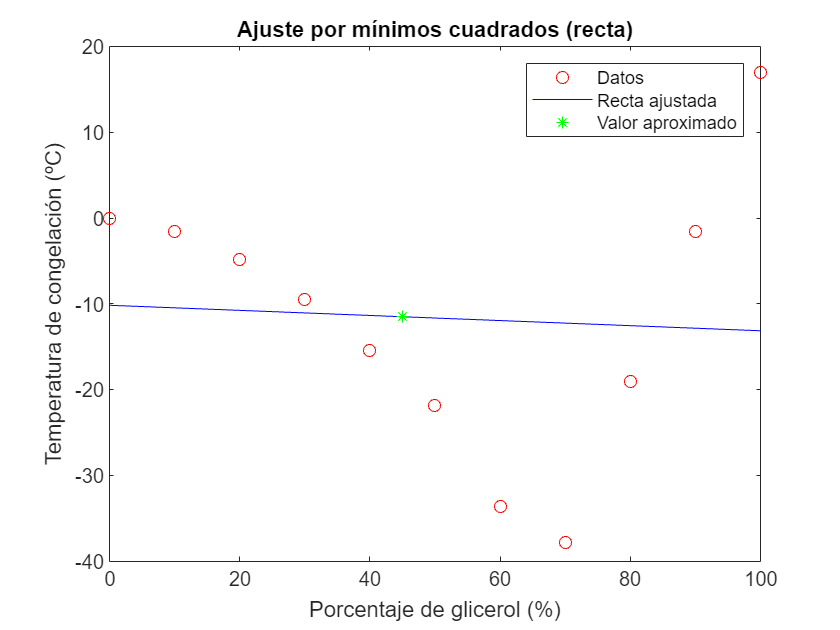

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
% Ajuste por mínimos cuadrados (recta)
p = polyfit(porcentaje, temperatura, 1);
recta = polyval(p, x_plot);

% Evaluar la recta ajustada en 45% de glicerol
y_pred_recta = polyval(p, x_pred);

% Graficar los datos, el valor aproximado y la recta ajustada
figure
plot(porcentaje, temperatura, 'ro', x_plot, recta, 'b-', x_pred, y_pred_recta, 'g*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Recta ajustada', 'Valor aproximado');
title('Ajuste por mínimos cuadrados (recta)');

#### Exercici 7. Ajust per mínims quadrats (cúbica)

- Valor aproximat cúbica

- Grafica de les dades, el valor aproximat i el polinomi interpolador

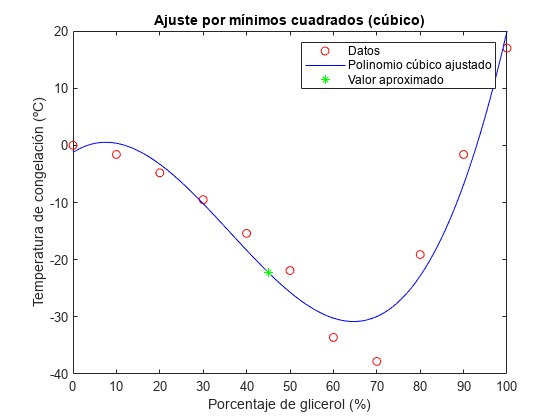

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
% Ajuste por mínimos cuadrados (cúbico)
p_cubico = polyfit(porcentaje, temperatura, 3);
cubica = polyval(p_cubico, x_plot);

% Evaluar el polinomio cúbico ajustado en 45% de glicerol
y_pred_cubico = polyval(p_cubico, x_pred);

% Graficar los datos, el valor aproximado y el polinomio cúbico ajustado
figure
plot(porcentaje, temperatura, 'ro', x_plot, cubica, 'b-', x_pred, y_pred_cubico, 'g*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
legend('Datos', 'Polinomio cúbico ajustado', 'Valor aproximado');
title('Ajuste por mínimos cuadrados (cúbico)');

#### Exercici 8. Interpolació des de la finestra de gràfics

Representeu gràficament la taula de dades, cada node per un *, a continuació mitjançant el menú Tools de la finestra gràfica accediu a l'opció basic fitting i trobeu una corba que ajusti les dades.

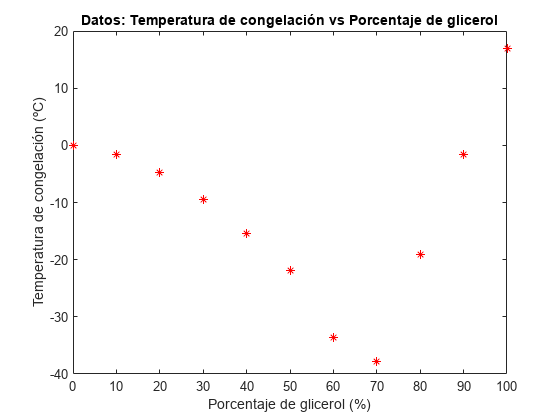

x=0:10:100; 
y=[0 -1.6 -4.8 -9.5 -15.4 -21.9 -33.6 -37.8 -19.1 -1.6 17];
% Graficar los datos con estrellas (*)
figure
plot(porcentaje, temperatura, 'r*');
xlabel('Porcentaje de glicerol (%)');
ylabel('Temperatura de congelación (ºC)');
title('Datos: Temperatura de congelación vs Porcentaje de glicerol');

`document preparat per M. Àngela Grau Gotés - març 2023`